# Diferencias Divididas de Newton

clear
clc
format rat
syms x
equis=[2 3 4];
y=[4 2 8];
n=length(equis);
filas=n;
columnas=n+1;
M=zeros(filas,columnas)

M =        0              0              0              0       
       0              0              0              0       
       0              0              0              0       


M(:,1)=equis

M =        2              0              0              0       
       3              0              0              0       
       4              0              0              0       


M(:,2)=y

M =        2              4              0              0       
       3              2              0              0       
       4              8              0              0       


k=n;
w=2;
ant_w=w;
for j=3:n+1
k;
    w=ant_w;
    for i=2:k
        fprintf('M(%i,%i)=(M(%i,%i)-M(%i,%i))/(M(%i,1)-M(%i,1))\n',i-1,j,i,j-1,i-1,j-1,w,i-1);
        M(i-1,j)=(M(i,j-1)-M(i-1,j-1))/(M(w,1)-M(i-1,1));
        w=w+1;
    end
    ant_w=ant_w+1;
    k=k-1;
end

M(1,3)=(M(2,2)-M(1,2))/(M(2,1)-M(1,1))
M(2,3)=(M(3,2)-M(2,2))/(M(3,1)-M(2,1))
M(1,4)=(M(2,3)-M(1,3))/(M(3,1)-M(1,1))


M

M =        2              4             -2              4       
       3              2              6              0       
       4              8              0              0       


diferencias=M(1,:)

diferencias =        2              4             -2              4       


sumatoria=M(1,2);
for j=3:length(diferencias)
    productoria=1;
    for i=1:j-2
        productoria=productoria*(x-equis(i));        
    end
    sumatoria=sumatoria+diferencias(j)*productoria;
end
sumatoria

$$sumatoria = 4\,\left(x-2\right)\,\left(x-3\right)-2\,x+8$$

modelo=simplify(sumatoria)

$$modelo = 4\,x^{2}-22\,x+32$$

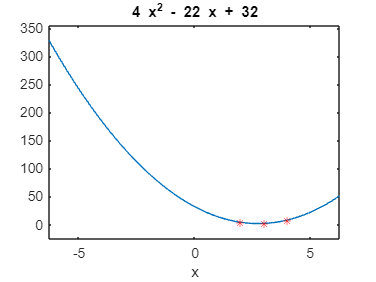

ezplot(modelo)
hold on
plot(equis,y,'r*')